%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path



clearvars %clear all variables
%clear all % clear all, men forsinker koden om den kjøres hver gang
% clf %clear all figures
% cla %clear all axis






# Komplekse tall

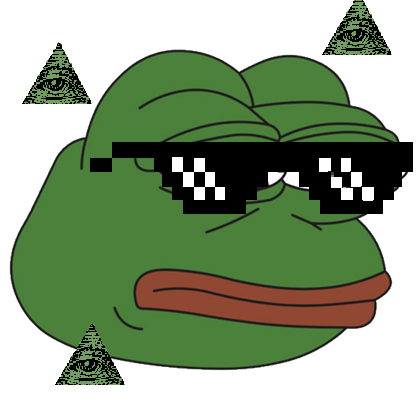

**Velg type evaluering**

typeEvaluering = 1;
 

**Evaluer et komplekst uttrykk**

Eksempel: 1/i-(1-i)/(1+i)

if typeEvaluering == 1
    z = sin(i)
    theta = sym(angle(z)); % Finner vinkel theta
    thetaDegrees = rad2deg(theta); % Vinkel theta i grader
    r = sym(abs(z)); % Modulus, absoluttverdi, r
    
    
    zConj = conj(z)
    zDivByZConj = z/zConj
    zTimesZConj = z*zConj
    expFormExponent = (i*theta); % Finner den eksponentielle delen av eksponentiell form. S338 i Engineering Mathematic.
    displayFormula(["'Eksponentiell form = e^('", string(expFormExponent),"')'"])
    disp(func2link(z))
end

z = 0.0000 + 1.1752i

zConj = 0.0000 - 1.1752i

zDivByZConj = -1

zTimesZConj = 1.3811

$$\mathrm{Eksponentiell form = e\hat{}(}\frac{\pi \,\mathrm{i}}{2})$$

<a href="https://www.wolframalpha.com/input/?i=0%2B1.1752i">Vis funksjon i wolfram</a>


**Evaluer en kompleks likning**

Eksempel: @(z) z^3==1

if typeEvaluering == 2

    
    
    syms z
    zEqn = "@(z) z^4==-1";
    zEqn = str2func(zEqn);
    disp(zEqn);
    z = solve(zEqn,z)

    theta = sym(angle(z)); % Finner vinkel theta i radianer
    thetaDegrees = rad2deg(theta); % Vinkel theta i grader
    r = sym(abs(z)); % Modulus, absoluttverdi, r
    
    zConj = conj(z)
    zDivByZConj = z./zConj
    zDivByZConjDouble = double(z./zConj)
    zTimesZConj = z.*zConj
    zTimesZConjDouble = double(z.*zConj)
    sumOfZs = sum(z)
end

**Cartesian Argand**

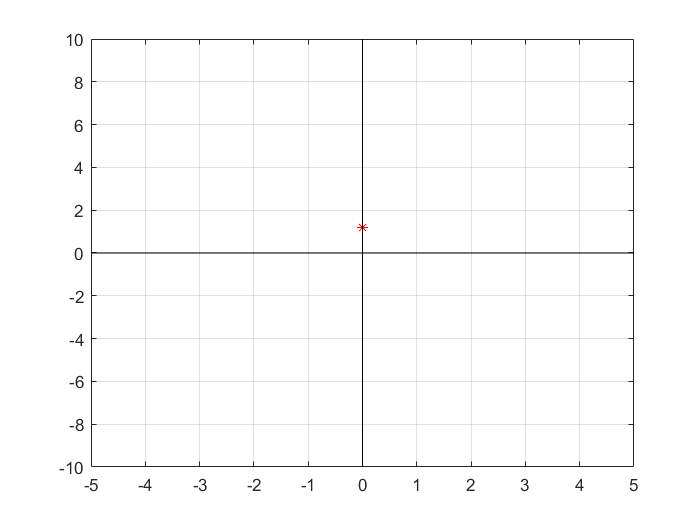

realPart = real(z);
imagPart = imag(z);

syms x
plot(z, '*',"Color",'red') % Plotter det komplekse tallet som et punkt
grid on
hold on
% axis([-5 1 -1 2]) % sett denne manuelt om zoomen blir feil
fplot(0,'color', 'black'); % lag y-linja
fplot(0,x, [-10 10],'color', 'black'); % lag x-linja

%% Fiks denne her sånnn at vektoren vises riktig. Vil ha en ORDENTLIG vektor
% if realPart < 0
%     fplot (@(x) imagPart/realPart, [realPart 0]) 
% else 
%     fplot (@(x) x/realPart, [0 realPart]) 
% end
hold off

**Polar Argand**

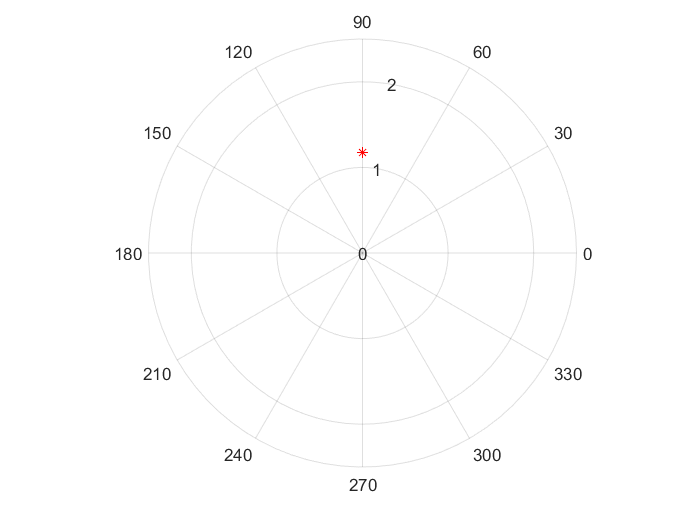

polarplot(z,'*',"Color",'red')
rlim('auto') % hent denne verdien fra funksjonen

display(theta);

$$theta = \frac{\pi }{2}$$

display(thetaDegrees);

$$thetaDegrees = 90$$

display(r);

$$r = \frac{2646317828889793}{2251799813685248}$$

% displayFormula(["'Vinkel theta  =  '", string(theta), "' radianer  =  '", string(thetaDegrees), "' grader.'"]);
% displayFormula(["'Modulus r = '", string(r)])